%Set Conditions for Testing
D=30; %Prop Diameter
minThrust = 6.25;
normalize = 1;

% Extracting data from the table
x1 = x1T_MotorAntigravity7005_230.RotationSpeed_rpm_;
y1 = x1T_MotorAntigravity7005_230.ElectricalPower_W_;
z1 = x1T_MotorAntigravity7005_230.Thrust_kgf_;


x2=x2T_MotorAntigravity6007_320XXoarPJP.RotationSpeed_rpm_;
y2 = x2T_MotorAntigravity6007_320XXoarPJP.ElectricalPower_W_;
z2=x2T_MotorAntigravity6007_320XXoarPJP.Thrust_kgf_;


x3=x3Vertiq60_08KV300XT.RotationSpeed_rpm_;
y3=x3Vertiq60_08KV300XT.ElectricalPower_W_;
z3=x3Vertiq60_08KV300XT.Thrust_kgf_;


x4=x4ScorpionA_5025_220kv.RotationSpeed_rpm_;
y4 = x4ScorpionA_5025_220kv.ElectricalPower_W_;
z4 = x4ScorpionA_5025_220kv.Thrust_kgf_;


x5=x5T_MotorAntigravity6007II_.RotationSpeed_rpm_;
y5 = x5T_MotorAntigravity6007II_.ElectricalPower_W_;
z5 = x5T_MotorAntigravity6007II_.Thrust_kgf_;


x6=x6IM_8012_115kvLegatus12.RotationSpeed_rpm_;
y6 = x6IM_8012_115kvLegatus12.ElectricalPower_W_;
z6 = x6IM_8012_115kvLegatus12.Thrust_kgf_;


x7=x7TA110_20Kv80.RotationSpeed_rpm_;
y7 = x7TA110_20Kv80.ElectricalPower_W_;
z7 = x7TA110_20Kv80.Thrust_kgf_;


x8=x8T_motorU15V2Kv80.RotationSpeed_rpm_;
y8 = x8T_motorU15V2Kv80.ElectricalPower_W_;
z8 = x8T_motorU15V2Kv80.Thrust_kgf_;


x9=x9U15XXLA.RotationSpeed_rpm_;
y9 = x9U15XXLA.ElectricalPower_W_;
z9 = x9U15XXLA.Thrust_kgf_;


% Standarize Propeller length using T ∝ D²

if normalize==1 
DR1=D/PropSpec(1,1);
z1=z1*(DR1^2);

DR2 = D / PropSpec(2, 1);
z2 = z2 * (DR2^2);

DR3=D/PropSpec(3,1);
z3 = z3 * (D / PropSpec(3, 1))^2;

DR4 = D / PropSpec(4, 1);
z4 = z4 * (DR4^2);

DR5 = D / PropSpec(5, 1);
z5 = z5 * (DR5^2);

DR6 = D / PropSpec(6, 1);
z6 = z6 * (DR6^2);

DR7 = D / PropSpec(7, 1);
z7 = z7 * (DR7^2);

DR8 = D / PropSpec(8, 1);
z8 = z8 * (DR8^2);

DR9 = D / PropSpec(9,1);
z9 = z9 * (D / PropSpec(9, 1))^2;
end

clear("x");
clear('y"');
clear("z");

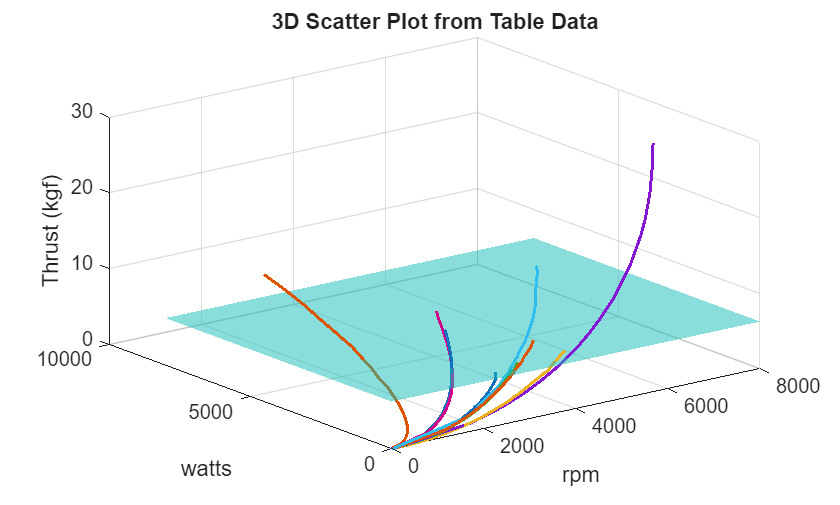

% Creating a 3D scatter plot
figure;
plot3(x1, y1, z1, '-', 'MarkerSize', 5, 'LineWidth', 1.5); % Line connecting the points
hold on
plot3(x2, y2, z2, '-', 'MarkerSize', 5, 'LineWidth', 1.5); % Line connecting the points
plot3(x3,y3,z3,'-','MarkerSize',5, 'LineWidth',1.5);
plot3(x4, y4, z4, '-', 'MarkerSize', 5, 'LineWidth', 1.5);
plot3(x5, y5, z5, '-', 'MarkerSize', 5, 'LineWidth', 1.5);
plot3(x6, y6, z6, '-', 'MarkerSize', 5, 'LineWidth', 1.5);
plot3(x7, y7, z7, '-', 'MarkerSize', 5, 'LineWidth', 1.5);
plot3(x8, y8, z8, '-', 'MarkerSize', 5, 'LineWidth', 1.5);
plot3(x9, y9, z9, '-', 'MarkerSize', 5, 'LineWidth', 1.5);

% Create a grid for the plane
[xPlane, yPlane] = meshgrid(linspace(0, 8000, 10), linspace(0, 8000, 10));
zPlane = minThrust * ones(size(xPlane)); % Set z values to minThrust

% Plot the plane
surf(xPlane, yPlane, zPlane, 'FaceAlpha', 0.5, 'EdgeColor', 'none'); % Semi-transparent plane

hold off; % Release the hold on the current figure
xlabel('rpm');
ylabel('watts');
zlabel('Thrust (kgf)');
title('3D Scatter Plot from Table Data');
grid on;

x1 = x1T_MotorAntigravity7005_230.RotationSpeed_rpm_;
x2 = x2T_MotorAntigravity6007_320XXoarPJP.RotationSpeed_rpm_;
x3 = x3Vertiq60_08KV300XT.RotationSpeed_rpm_;
x4 = x4ScorpionA_5025_220kv.RotationSpeed_rpm_;
x5 = x5T_MotorAntigravity6007II_.RotationSpeed_rpm_;
x6 = x6IM_8012_115kvLegatus12.RotationSpeed_rpm_;
x7 = x7TA110_20Kv80.RotationSpeed_rpm_;
x8 = x8T_motorU15V2Kv80.RotationSpeed_rpm_ ;
x9 = x9U15XXLA.RotationSpeed_rpm_;

y1=x1T_MotorAntigravity7005_230.Voltage_V_;
y2 = x2T_MotorAntigravity6007_320XXoarPJP.Voltage_V_;
y3 = x3Vertiq60_08KV300XT.Voltage_V_;
y4 = x4ScorpionA_5025_220kv.Voltage_V_;
y5 = x5T_MotorAntigravity6007II_.Voltage_V_;
y6 = x6IM_8012_115kvLegatus12.Voltage_V_;
y7 = x7TA110_20Kv80.Voltage_V_;
y8 = x8T_motorU15V2Kv80.Voltage_V_;
y9 = x9U15XXLA.Voltage_V_;

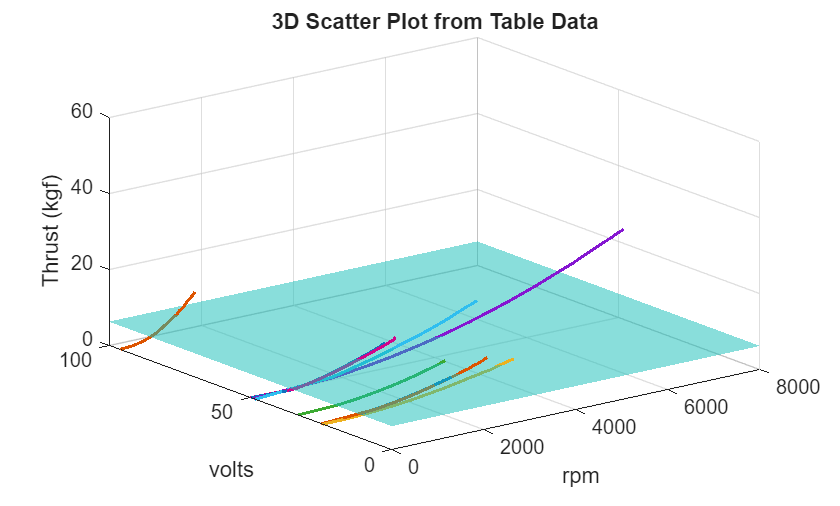

% Creating a 3D scatter plot
figure;
plot3(x1, y1, z1, '-', 'MarkerSize', 5, 'LineWidth', 1.5); % Line connecting the points
hold on
plot3(x2, y2, z2, '-', 'MarkerSize', 5, 'LineWidth', 1.5); % Line connecting the points
plot3(x3,y3,z3,'-','MarkerSize',5, 'LineWidth',1.5);
plot3(x4, y4, z4, '-', 'MarkerSize', 5, 'LineWidth', 1.5);
plot3(x5, y5, z5, '-', 'MarkerSize', 5, 'LineWidth', 1.5);
plot3(x6, y6, z6, '-', 'MarkerSize', 5, 'LineWidth', 1.5);
plot3(x7, y7, z7, '-', 'MarkerSize', 5, 'LineWidth', 1.5);
plot3(x8, y8, z8, '-', 'MarkerSize', 5, 'LineWidth', 1.5);
plot3(x9, y9, z9, '-', 'MarkerSize', 5, 'LineWidth', 1.5);
ylim([0 100]); % Set y-axis limits to range from 0 to 100 volts
zlim([0 60]); % Set y-axis limits to range from 0 to 100 volts


% Create a grid for the plane
[xPlane, yPlane] = meshgrid(linspace(0, 8000, 10), linspace(0, 8000, 10));
zPlane = minThrust * ones(size(xPlane)); % Set z values to minThrust

% Plot the plane
surf(xPlane, yPlane, zPlane, 'FaceAlpha', 0.5, 'EdgeColor', 'none'); % Semi-transparent plane

hold off; % Release the hold on the current figure
xlabel('rpm');
ylabel('volts');
zlabel('Thrust (kgf)');
title('3D Scatter Plot from Table Data');
grid on;